Segundo Examen Parcial Primavera 2022

- Demuestra que el algoritmo de Gauss-Seidel puede escribirse como:

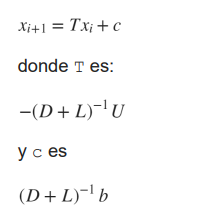

Pega aquí tu respuesta:

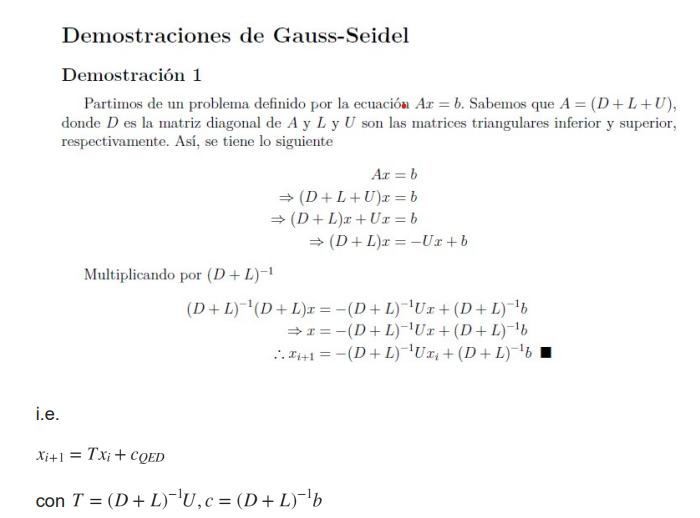

           2. Codifica de manera eficiente, al final del script, el método esPositivaDefinida(A) empleado el criterio de Sylverster y la función "det" de MATLAB.

3. Utiliza el método codificado en la pregunta anterior para determinar si la matriz A es positiva definida. Plan B (con penalización): puedes usar una línea de código para responder esta pregunta directamente. 

A = [10,-1,2,0;-1,11,-1,3;2,-1,10,-1;0,3,-1,8]

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8



Par2_positivaDefinida1(A)

Unrecognized function or variable 'Par2_positivaDefinida1'.

4. Escribe, al final del script, la función "gradiente(f,x,h) que calcula numéricamente el gradiente de la función excalar f:R^n-->R en el vector X. La función debe utilizar el método de diferencias centrales con paso H. 

Prueba la función calculando el gradiente de f(x,y,z) = 5x^3*y*z^2 en el punto p=[1;2;3] con h = 0.0001.

h = 0.0001
f = @(x) 5*x(1)^3*x(2)*x(3)^2
del = Par2_gradiente(f, [1 2 3], h)

5. Utiliza tu algoritmo Gasuu-Seidel (cópialo más abajo) para resolver e sitema Ax = b, dónde: ...

A = [0.1,7,-0.3; 3,-0.1,-0.2; 0.3,-0.2,10]
b = [-19.3;7.85;71.4]

Dado que "A" no es escrictamente diagonal dominante, primero intercambia los rengolnes 1 y 2 de A y de b utilizando una matriz" P" de permitación (o un vector "p" de ptermitación=

Escribe aquí la matriz P de permitación:

P = eye(3)
p = [2 1 3]
P = P(:,p)

Intercambia los renglones de A y de b utilizando P

PA = P*A
Pb = (b'*P)'

Ya con los renglones intercambiados, usa el método Gauss-Seidel para resolver el sistema de ecuaciones. 

Par2_esDiagonalDominante(PA)
[x, i] = Par2_gaussSeidel2(PA, Pb)
xxx = all(diag(PA))


6. Utilizando un método iterativo (que debes pegar más abajo) resuelve el siguiente sistema de ecaciones en 3 o menos interaciones.

A = [4,-1,0;-1,4,-1;0,-1,4]
b = [2;6;2]
x0 = ones(3,1)
[x,i] = Par2_gradienteConjugado(A, b, x0)



7. Usando el método de Newton Raphson de varias variables (que debes pegar abajo) encuentra un punto común de tres esferas con radio 5 con centros en (1, - 2, 0), (-2, 2, -1) y (4, -2, 3).

Considera como valor inicial x0 = [-1;-1;-1]

syms x y z
xs = [x;y;z]
f1 = (x-1)^2 + (y+2)^2 + z^2 - 25
f2 = (x+2)^2 + (y-2)^2 + (z+1)^2 - 25
f3 = (x-4)^2 + (y+2)^2 + (z-3)^2 - 25
fs = [f1;f2;f3]
Js = jacobian(fs, xs)
f = matlabFunction(fs, 'Vars', {xs})
J = matlabFunction(Js, 'Vars', {xs})

x0 = [-1;-1;-1]
[x,i] = Par2_newtonRaphsonVV(f, J, x0)


